# Imports

% for stimulator
folder = 'NewBoardTest';
addpath(genpath(folder));

% 
ComPort        = 'COM28';
Baudrate       = 115200*8;   %921600
 
run('OpenComPort.m'); %

clc;

addpath(genpath('MEP_Detection'));  %to have the MEP functions
addpath(genpath('LINK')); %to have the Matlab-DataLink connection functions

% Specify the folder path to save the data
folderPath = 'DATA/DOME/Double_Pulse'; % change this according to recording subject

% Check if the folder exists, if not, create it
if ~exist(folderPath, 'dir')
    mkdir(folderPath);
end

# Protocol

*follow*[* these steps *](matlab:open('./matlab_DL_link.pdf'))*for connecting Matlab to Biometrics Datalink*

- Launch the Biometrics Datalink

- The Biometrics Application MUST have file save mode turned off

- Run [DatalogInit.m](matlab:open('..\MATLAB\DataLogInit.m')) 

%DataLogInit

        4. Setup a sensor and record it in the Biometrics Application

        5. Select Channel and set parameters

        6. Run [getDataFromChannel.m](matlab:open('./getDataFromChannel.m')) to extract real time data

%getDataFromChannel(channel,sampleRate,numberOfValues);

         7. Run MEP detection to detect MEP in real time by using functions in the MEP folder

### **IMPORTANT : The Data can only be acquired for 50000 samples (50s if 1000 sf) before the data overflows. After 50s STOP and START the EMG recording.**

Remarks : 

- You cannot send twice the same samples so NO OVERLAPPING WINDOWS. Practically this means if you take windows of 2s, when you press the first time 'getDataFromChannel' you will get the 2s window. However if you press a second time on 'getDataFromChannel' before waiting 2s, you will only get the remaining. Example: for a 2s window, sending data request 1.5s after the first request will only give you a 1.5s window since 0.5s overlap with the previous window.

- In the same lines, if your window is bigger than the elapsed time from the start of the recording you will only get the available samples. Example : for a 2s window, press START at t = 0, sending data request after 1s will only get you a 1s window.

- The EMG seems to take windows following each other even if we are far in time : if you take a 5s window at time 10s it will take window 0-5s not 5-10s so if you need to do pauses make sure you get the data of the pause before getting data of interest.

# Set Parameters

With the following parameters we have a first pulse of 10ms, interpulse interval of 50ms, interframe interval of 5s.

selectedChannels = {0,1,2,3,4,5}; % channel to record from, multiple channels will be used later. Channel 0 here is channel 1 on BIOMETRICS
channelNames = {'SO_R','SO_L','TA_R','TA_L','RF_R','RF_L'};
sf = 1000; %sampling frequency of channel acquisition


% EMG preprocessing
plot_chs = false;
bool_plot_PSD = false;
selected_filters = 3;
paper_nb = 1;

% MEP detection
bool_plot_MEP = true;


SetSingleChanState(s, 0, 1, 1, 0); %should turn red
%SetSingleChanState(s, 1, 1, 1, 0); %for channel 1


% Stimulation Variables
pulse_width = uint32(490); % us --- Fixed --- Remember this is half of the duration of a bi-phasic pulse
pulse_width_1pulse = uint32(1000); % us --- Fixed --- The total duration of a burster (made of several short bi-phasic pulses)
N_pulse_repetition = 2;     % --- Insert 1 to Single Pulse (SP)-  2 to Double Pulse (DP) --- the number of inner bi-phasic pulses in a burster.   
interpulse_duration = uint32(50 *1000); % us - ms --- for Double pulse. Usually between 35-100ms --- time between two bi-phasic pulses. 
pulse_deadtime = uint32(20);        % us - --- Fixed ---  20 is the minimum
interframe_duration = uint32( 5000000 ); % us - s 
%burst_interframe_duration = uint32( 1e6 * 1/STIMULATION_FREQ - ...    % --- Not used for PRM reflex --- 
%                                       (burst_inner_pulse_repetition * (2 * burst_single_phase_pulse_duration + burst_pulse_deadtime) ) ... % the total duration of the bi-phasic pulses including deadtime
%                                       ) ; % us. This is the time between two bursters. - Not necessary for SP and DP
current =  15; % mA
max_current = 10; % mA


# Prepare Stimulator parameters

SetSingleChanAllParam_v2(s, 0, ...
                        pulse_width, ...    % pulseDurationUS
                        pulse_deadtime, ...                 % deadTimeUS
                        interpulse_duration, ...            % interpulseDurationUS
                        interframe_duration, ...            % interframeDurationUS
                        N_pulse_repetition, ...         % numberOfPulsesPerFrame
                        current,...               % IAmplitude in mA
                        0);

%% Enable Trigger Mode
SetSingleChanSingleParam_v2(s, 0, 7, 0) % Trigger mode (7), Output
SetSingleChanState(s, 0, 1, 0, 0) %  Output disabled

# Real time MEP detection

In this part we aim to detect in real time the Muscle Evoked Potentials at each stimulation. To do so, we perform 3 repetitions at each current value, increasing the current by steps of 5mA. We collect the data, preprocess it and analyze the response.

%% Enable Trigger Mode
SetSingleChanSingleParam_v2(s, 0, 7, 0) % Trigger mode (7), Output
SetSingleChanState(s, 0, 1, 0, 0) %  Output disabled 


current = 15;

SetSingleChanAllParam_v2(s, 0, ...
                        pulse_width, ...    % pulseDurationUS
                        pulse_deadtime, ...                 % deadTimeUS
                        interpulse_duration, ...            % interpulseDurationUS
                        interframe_duration, ...            % interframeDurationUS
                        N_pulse_repetition, ...         % numberOfPulsesPerFrame
                        current,...               % IAmplitude in mA
                        0);

SetSingleChanState(s, 0, 1, 1, 1);

SetSingleChanSingleParam_v2(s, 0, 9, 1);

%params to tune each time : current_0 and real_time_channel
% can also tune pause(0.920) updated t_0 for synchronization if they change

folderPath = 'DATA/DOME/Double_Pulse';
% Check if the folder exists, if not, create it

if ~exist(folderPath, 'dir')
    mkdir(folderPath);
end

current_0 = 20; %set the current to start the loop with.
real_time_channels = selectedChannels; % set the real time channel

numberOfrepetitions = 3; %i value
numberOfcurrents = 2; %j value
numberOfchannels = length(real_time_channels);

all_responses = cell(numberOfcurrents, numberOfrepetitions,numberOfchannels); % jxixn array of responses
all_amplitudes = cell(numberOfcurrents, numberOfrepetitions,numberOfchannels); % jxixn array of amplitudes of first MEP
all_emgs = cell(numberOfcurrents, numberOfrepetitions,numberOfchannels); % jxixn array of all emg windows

numberOfValues = 5000;

current_initial = 15; % small comfortable current to only see artifact
SetSingleChanSingleParam(s, 0, 6, current_initial);

SetSingleChanState(s, 0, 1, 1, 0); % activate High Voltage
pause(2)
SetSingleChanState(s, 0, 1, 1, 1); % activate output

start_time = tic;

emg_removed = getDataFromChannels(real_time_channels,sf,40000); % remove available samples before recording

t_0 = 1000; % we record windows starting 1s before stimulation (see pause(0.920) line  112)
theoretical_elapsed_time = 0;
offset = 0;

emg_removed = getDataFromChannels(real_time_channels,sf,40000); % remove available samples before recording

SetSingleChanSingleParam(s, 0, 6, current_0)


getData returned 0 from channel 0
getData returned 0 from channel 1
getData returned 0 from channel 2
getData returned 0 from channel 3
getData returned 0 from channel 4
getData returned 0 from channel 5


Repetition: 1


Current: 20


Looking at pulse at time t_0 = : 960


INTERPULSE FIRST
   50

    1.0116

PEAKS
     6     1

lOCS
   356
   394
   445
   475
   508
   589

ok1
not ok 2


Response for current 20, repetition 1, channel 1: no or invalid response


INTERPULSE FIRST
   50

    1.8236

PEAKS
     4     1

lOCS
   394
   445
   475
   645

ok1
ok2


Response for current 20, repetition 1, channel 2: presumed M-wave


INTERPULSE FIRST
   50

    1.2979

PEAKS
     4     1

lOCS
    70
   171
   394
   445

ok1
not ok 2


Response for current 20, repetition 1, channel 3: no or invalid response


INTERPULSE FIRST
   50

    2.3192

PEAKS
     1     1

lOCS
   579



Response for current 20, repetition 1, channel 4: reflex response


INTERPULSE FIRST
   50

    0.8385

PEAKS
     7     1

lOCS
   362
   393
   444
   473
   534
   557
   596

ok1
not ok 2


Response for current 20, repetition 1, channel 5: no or invalid response


INTERPULSE FIRST
   50

    0.2901

PEAKS
     6     1

lOCS
   394
   445
   472
   522
   547
   572

ok1
not ok 2


Response for current 20, repetition 1, channel 6: no or invalid response


Processing time: 1.8769 seconds


Repetition: 2


Current: 20


Looking at pulse at time t_0 = : 920


INTERPULSE FIRST
   50

    1.0169

PEAKS
     7     1

lOCS
    12
   164
   430
   481
   508
   545
   567

ok1
ok2


Response for current 20, repetition 2, channel 1: presumed M-wave


INTERPULSE FIRST
   50

    1.1762

PEAKS
     6     1

lOCS
   228
   353
   430
   481
   510
   547

ok1
ok2


Response for current 20, repetition 2, channel 2: presumed M-wave


INTERPULSE FIRST
   50

    1.3441

PEAKS
     4     1

lOCS
    88
   430
   481
   510

ok1
not ok 2


Response for current 20, repetition 2, channel 3: no or invalid response


INTERPULSE FIRST
   50

    2.9487

PEAKS
     2     1

lOCS
   431
   482

ok1
ok2


Response for current 20, repetition 2, channel 4: presumed M-wave


INTERPULSE FIRST
   50

    0.7384

PEAKS
     5     1

lOCS
   306
   430
   481
   509
   637

ok1
not ok 2


Response for current 20, repetition 2, channel 5: no or invalid response


INTERPULSE FIRST
   50

    0.9631

PEAKS
     6     1

lOCS
   214
   273
   309
   430
   481
   511

ok1
ok2


Response for current 20, repetition 2, channel 6: presumed M-wave


Processing time: 0.1712 seconds


Repetition: 3


Current: 20


Looking at pulse at time t_0 = : 880


INTERPULSE FIRST
   50

    0.9682

PEAKS
     8     1

lOCS
   173
   424
   467
   497
   518
   549
   572
   605

ok1
ok2


Response for current 20, repetition 3, channel 1: presumed M-wave


INTERPULSE FIRST
   50

    1.1239

PEAKS
     5     1

lOCS
   166
   467
   518
   549
   582

ok1
not ok 2


Response for current 20, repetition 3, channel 2: no or invalid response


INTERPULSE FIRST
   50

    1.3311

PEAKS
     5     1

lOCS
    13
   372
   467
   518
   624

ok1
ok2


Response for current 20, repetition 3, channel 3: presumed M-wave


INTERPULSE FIRST
   50

    2.4663

PEAKS
     2     1

lOCS
   467
   518

ok1
not ok 2


Response for current 20, repetition 3, channel 4: no or invalid response


INTERPULSE FIRST
   50

    0.7642

PEAKS
     5     1

lOCS
   355
   389
   466
   517
   547

ok1
ok2


Response for current 20, repetition 3, channel 5: presumed M-wave


INTERPULSE FIRST
   50

    0.9225

PEAKS
     7     1

lOCS
    91
   403
   467
   518
   551
   579
   603

ok1
ok2


Response for current 20, repetition 3, channel 6: presumed M-wave


Processing time: 0.1472 seconds


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


Repetition: 1


Current: 25


Looking at pulse at time t_0 = : 960


INTERPULSE FIRST
   50

    1.0092

PEAKS
     7     1

lOCS
   120
   339
   384
   435
   466
   498
   522

ok1
not ok 2


Response for current 25, repetition 1, channel 1: no or invalid response


INTERPULSE FIRST
   50

    1.1534

PEAKS
     4     1

lOCS
   384
   435
   468
   553

ok1
not ok 2


Response for current 25, repetition 1, channel 2: no or invalid response


INTERPULSE FIRST
   50

    1.4299

PEAKS
     6     1

lOCS
   307
   384
   435
   466
   488
   634

ok1
not ok 2


Response for current 25, repetition 1, channel 3: no or invalid response


INTERPULSE FIRST
   50

    2.8681

PEAKS
     2     1

lOCS
   384
   435

ok1
not ok 2


Response for current 25, repetition 1, channel 4: no or invalid response


INTERPULSE FIRST
   50

    0.8075

PEAKS
     4     1

lOCS
   383
   434
   465
   528

ok1
not ok 2


Response for current 25, repetition 1, channel 5: no or invalid response


INTERPULSE FIRST
   50

    0.9779

PEAKS
     5     1

lOCS
   360
   384
   435
   471
   648

ok1
not ok 2


Response for current 25, repetition 1, channel 6: no or invalid response


Processing time: 0.1629 seconds


Repetition: 2


Current: 25


Looking at pulse at time t_0 = : 920


INTERPULSE FIRST
   50

    1.1447

PEAKS
     4     1

lOCS
   420
   471
   502
   568

ok1
ok2


Response for current 25, repetition 2, channel 1: presumed M-wave


INTERPULSE FIRST
   50

    1.6899

PEAKS
     3     1

lOCS
   421
   472
   507

ok1
not ok 2


Response for current 25, repetition 2, channel 2: no or invalid response


INTERPULSE FIRST
   50

    1.5242

PEAKS
     3     1

lOCS
   323
   421
   472

ok1
ok2


Response for current 25, repetition 2, channel 3: presumed M-wave


INTERPULSE FIRST
   50

    3.1503

PEAKS
     2     1

lOCS
   421
   472

ok1
ok2


Response for current 25, repetition 2, channel 4: presumed M-wave


INTERPULSE FIRST
   50

    0.8135

PEAKS
     6     1

lOCS
   172
   356
   420
   471
   501
   533

ok1
ok2


Response for current 25, repetition 2, channel 5: presumed M-wave


INTERPULSE FIRST
   50

    1.0648

PEAKS
     8     1

lOCS
   357
   400
   421
   472
   508
   534
   563
   604

ok1
ok2


Response for current 25, repetition 2, channel 6: presumed M-wave


Processing time: 0.1653 seconds


Repetition: 3


Current: 25


Looking at pulse at time t_0 = : 880


INTERPULSE FIRST
   50

    1.0689

PEAKS
     7     1

lOCS
   359
   393
   458
   488
   509
   537
   617

ok1
ok2


Response for current 25, repetition 3, channel 1: presumed M-wave


INTERPULSE FIRST
   50

    1.0768

PEAKS
    11     1

lOCS
    41
   126
   203
   314
   367
   458
   488
   509
   538
   561
   633

ok1
not ok 2


Response for current 25, repetition 3, channel 2: no or invalid response


INTERPULSE FIRST
   50

    1.4407

PEAKS
     3     1

lOCS
   192
   458
   509

ok1
not ok 2


Response for current 25, repetition 3, channel 3: no or invalid response


INTERPULSE FIRST
   50

    3.1481

PEAKS
     2     1

lOCS
   458
   509

ok1
not ok 2


Response for current 25, repetition 3, channel 4: no or invalid response


INTERPULSE FIRST
   50

    0.8989

PEAKS
     7     1

lOCS
   350
   426
   457
   486
   509
   541
   585

ok1
not ok 2


Response for current 25, repetition 3, channel 5: no or invalid response


INTERPULSE FIRST
   50

    1.0760

PEAKS
     4     1

lOCS
   458
   509
   542
   627

ok1
ok2


Response for current 25, repetition 3, channel 6: presumed M-wave


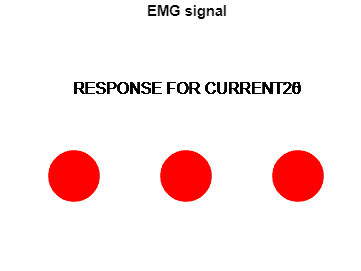

Processing time: 0.1584 seconds


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


END


pause(0.920); % pause accounts for delay when sending the next command SetSingleChanSingleParam_v2(s, 0, 9, 1). Based on tests.

SetSingleChanSingleParam_v2(s, 0, 9, 1);


for j = 1: numberOfcurrents    % Need to be increased
    current =  current_0 + (j-1)*5; % mA, it will start the first 3 repetitions at current_0
    SetSingleChanSingleParam(s, 0, 6, current)
    

    for i = 1: numberOfrepetitions  % Number of repetitions

        % Enable Output
        pause(5)
        %collect EMG data and process it
        for_timer = tic; % start timer
        theoretical_elapsed_time = theoretical_elapsed_time+5;
        offset = offset+ toc(start_time)-theoretical_elapsed_time;
        
        % CHANGE OFFSET DAILY BASED ON OFFSET TESTS. EITHER -50 , 0 , +50
        
        %updated_t_0 = t_0 +offset+49*i; %offset is computation time and 49(ms) is the time shift of each window
        updated_t_0 = t_0-40*i; %offset is computation time and 49(ms) is the time shift of each window

        disp(['Repetition: ', num2str(i)]);
        disp(['Current: ', num2str(current)]);
        emg_data = getDataFromChannels(real_time_channels,sf,numberOfValues); % collect data

        disp(['Looking at pulse at time t_0 = : ', num2str(updated_t_0)]);
        
       
        for k = 1:numberOfchannels  % Loop over channels
            [norm_factor_afterfilter, EMG_preprocessed] = EMG_preprocessing((double(emg_data(k,:)))', sf, selected_filters, 0, plot_chs, selectedChannels, bool_plot_PSD, paper_nb); %preprocess

            [response,p2p_amplitude] = ActionPotDetectDoublePulse3(updated_t_0,EMG_preprocessed, interpulse_duration/1000,norm_factor_afterfilter,bool_plot_MEP,numberOfValues); %find response 'no response', 'MEP reflex', 'M-wave', 'invalid'

            all_responses{j, i,k} = response;  
            all_amplitudes{j, i,k} = p2p_amplitude;  
            emg = emg_data(k, :);
            all_emgs{j, i, k} = emg; % Store EMG data for the current channel

            fprintf('Response for current %d, repetition %d, channel %d: %s\n', current, i, k,response);
            plot_response(all_responses(j, :,k),current);
            % Save the data in the 'DATA' folder

            filename = fullfile(folderPath, sprintf('emg_channel%s_current%d_repetition%d_window%ss_interpulse%s.mat', channelNames{k},current,i,num2str(numberOfValues/sf),num2str(interpulse_duration/1000)));
            save(filename, 'emg'); % saving raw data
        end

        

        elapsed_time_loop = toc(for_timer); % stop timer
        fprintf('Processing time: %.4f seconds\n', elapsed_time_loop);

        
    end
    disp("%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%")
    
    
end
SetSingleChanState(s, 0, 1, 0, 0);

disp("END")